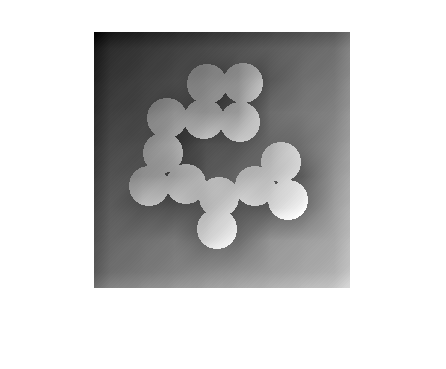

t = imread("circles.tif");
[x,y] = meshgrid(1:256,1:256);
t2 = double(t).*((x+y)/2+64)+x+y;
t3 = uint8(255*mat2gray(t2));

J = adapthisteq(t3);
imshow(J);

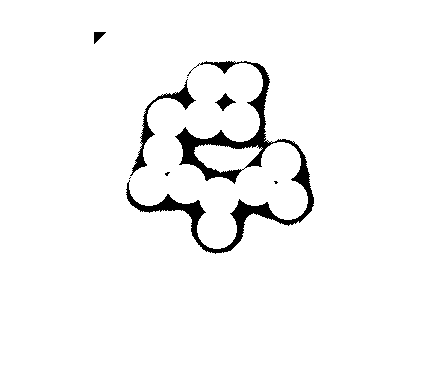

t4 = imbinarize(J,Threshold*graythresh(J));
imshow(t4);